clear all;
close all;
clc;

syms a0 a1 a2 d0 q1 q2 q3 q4 q5 qg real ;
a0 = 0.075; 
a1 = 0.3; a2 = 0.3; d0 = 0.25;

dh1 = [pi/2, -a0, 0, q1+pi/2];
dh2 = [0, a1, 0, q2];
dh3 = [0, a2, 0, q3];
dh4 = [0, a2, 0, q4];
dh5 = [0, a1, 0, (q5+pi/2)];
dh6 = [-pi/2, a0, 0, 0];

Transformation matrices

T01 = (transformation(dh1));
T12 = (transformation(dh2));
T23 = (transformation(dh3));
T34 = (transformation(dh4));
T45 = (transformation(dh5));
T56 = (transformation(dh6));

T02 = vpa(simplify(T01*T12));
T03 = vpa(simplify(T01*T12*T23));
T04 = vpa(simplify(T01*T12*T23*T34));
T05 = vpa(simplify(T01*T12*T23*T34*T45));
T06 = vpa(simplify(T01*T12*T23*T34*T45*T56));

Position Vector

P06 = vpa(simplify(T06(1:3,4)));

% q = [q1 q2 q3 q4 q5];
% q_new = [0 15*pi/180 160*pi/180 -20*pi/180 10*pi/180];
% P06 = vpa(subs(P06,q,q_new))

Orientation Vector

n = simplify(T06(1:3,1));

Sliding Vector

s = simplify(T06(1:3,2));

Jacobian Matrix

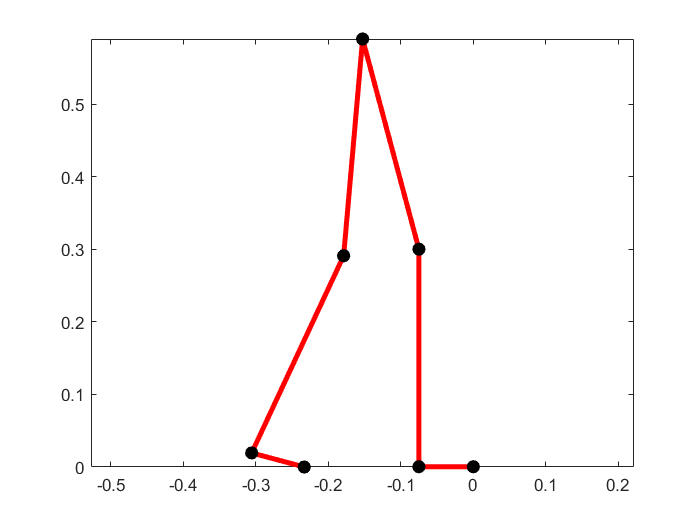

J06 = [diff(P06,q1),diff(P06,q2),diff(P06,q3),diff(P06,q4),diff(P06,q5)];


x1 = T01(1,4);
y1 = T01(3,4);
x2 = T02(1,4);
y2 = T02(3,4);
x3 = T03(1,4);
y3 = T03(3,4);
x4 = T04(1,4);
y4 = T04(3,4);
x5 = T05(1,4);
y5 = T05(3,4);
x6 = T06(1,4);
y6 = T06(3,4);

q = [q1 q2 q3 q4 q5];
q_new = [0 15*pi/180 160*pi/180 -20*pi/180 10*pi/180];
x2 = subs(x2,q,q_new);
y2 = subs(y2,q,q_new);
x3 = subs(x3,q,q_new);
y3 = subs(y3,q,q_new);
x4 = subs(x4,q,q_new);
y4 = subs(y4,q,q_new);
x5 = subs(x5,q,q_new);
y5 = subs(y5,q,q_new);
x6 = subs(x6,q,q_new);
y6 = subs(y6,q,q_new);


biped_c =  [0,x1,x2,x3,x4,x5,x6;
              0,y1,y2,y3,y4,y5,y6];


plot(biped_c(1,:),biped_c(2,:),'r-o','linewidth',3,'MarkerEdgeColor','k',...
                       'MarkerFaceColor','k',...
                       'MarkerSize',5)

%hold on

% t = (0:360)*pi/180;
% t=0:0.01:2*pi       
% path = plot(x6+0.06*(t-sin(t)),0.06*(1-cos(t)),'g--','linewidth',1.5,'MarkerEdgeColor','g',...
%                        'MarkerFaceColor','g',...
%                        'MarkerSize',1);
% legend(path,'Expected Trajectory of the foot tip')
% 
% hold off

axis equal

Inverse kinematic solution using iterative method

Task Space Position

mu = [-0.2331334779; 0 ; -0.00038442603]; 

Initial assumed joint angles

q = [-0.0239; 0.2465; 2.7995; -0.3459; 0.1927];

%q = [0; 15*pi/180; 160*pi/180; -20*pi/180; 10*pi/180]; -> this should be answer


for i = 1:300
   % q1 = q(1,i)
   % q2 = q(2,i); 
   % q3 = q(3,i);  
    
    % Forward kinematic model
    mu_e = [simplify(T06(1,4)) ; simplify(T06(2,4)) ; simplify(T06(3,4))]; %planar
    vars = [a0, a1, a2, d0, q1, q2, q3, q4, q5];
    newVars = [0.1, 0.3, 0.3, 0.05, q(1,i), q(2,i), q(3,i), q(4,i), q(5,i)];
    mu_e = subs(mu_e,vars, newVars);
    
    % Error estimation
    del_mu = vpa(mu - mu_e);
    
    % Jacobain matrix
    J06_1= subs(J06,vars, newVars);
   
    % Newton method
    q(:,i+1) = q(:,i) + vpa(simplify(pinv(J06_1)))* del_mu;
    
    % Termination condition
    if abs(del_mu(1))<=1e-10 && abs(del_mu(2))<=1e-10 && abs(del_mu(3))<=1e-10
        qf = q(:,i+1)
        break
    end
end

qf =     0.0025
    0.2617
    2.7916
   -0.3474
    0.1799




mu_e = vpa(simplify(subs(mu_e,vars, newVars)))

$$mu\_e = \left(\begin{array}{c} -0.23313347789999781152378023376972\\ 0\\ -0.00038442603000108055891169675853434 \end{array}\right)$$